clc
clear
close all
rng('default');

set(0, 'defaultAxesFontSize', 12)
set(0, 'DefaultLineLineWidth', 2);
set(0, 'defaultAxesFontSize', 14)
set(0, 'defaultAxesTickLabelInterpreter','latex');
set(0, 'defaultlegendInterpreter','latex')

## Load data

load('data.mat');

% e(t) -> |model| -> y(t)  model?

## Pre-process data

Ninit = 500;
ys = y(Ninit+1:end);
es = e(Ninit+1:end);

fprintf("Media y: %d \n",mean(ys))

Media y: 1.280222e-02 


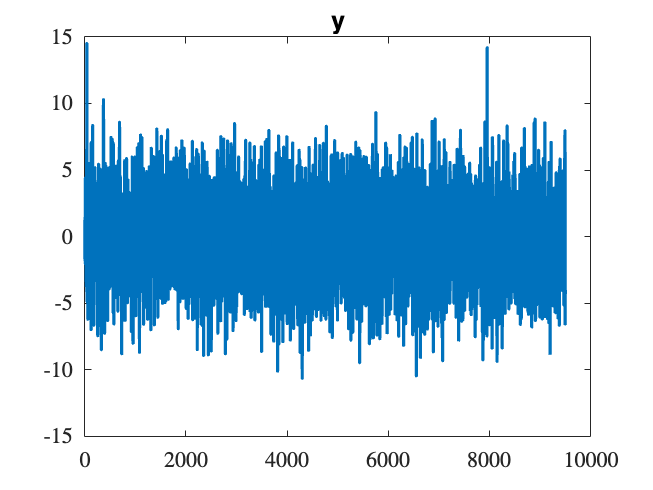


figure
plot([1:size(ys,1)],ys)
title("y")

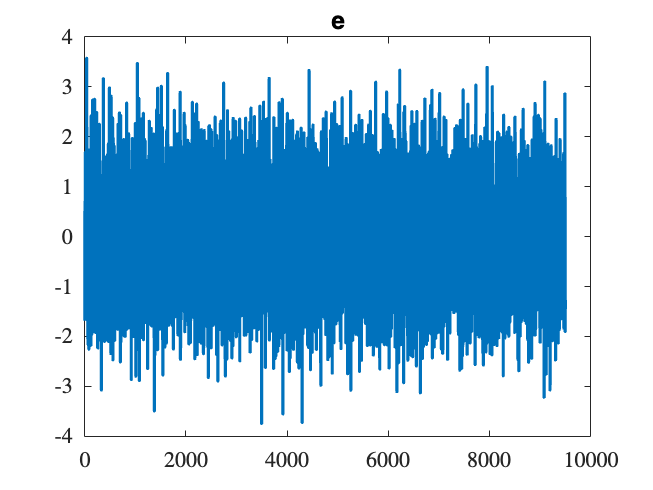


figure
plot([1:size(es,1)],es)
title('e')


% test stazionarietà
fprintf("ADF test su y(t): %d \n",adftest(ys))

ADF test su y(t): 1 


## Qual'è la varianza del processo?

lambda_2 = var(y);
fprintf("Varianza del processo: %d \n",lambda_2)

Varianza del processo: 8.597593e+00 


## Il processo è modellabile come un AR, MA o ARMA?

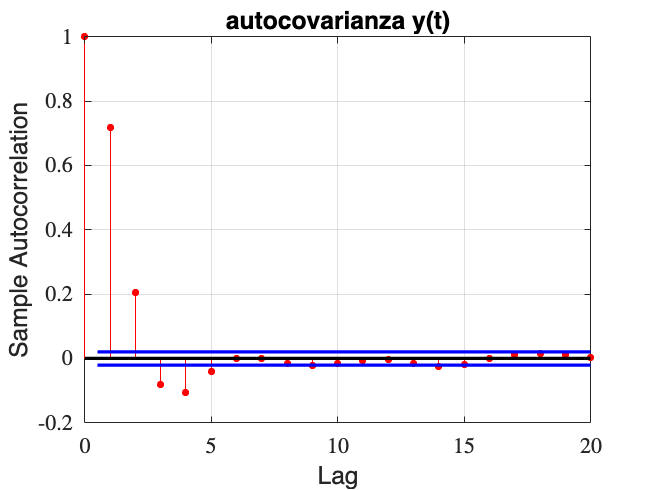

figure
autocorr(ys)
title("autocovarianza y(t)")

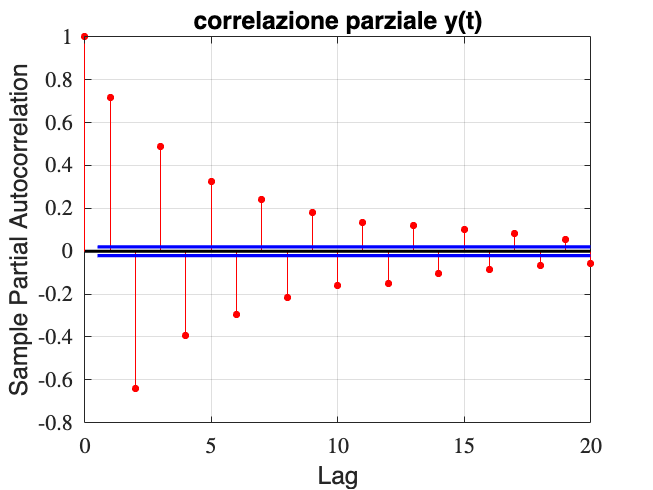

figure
parcorr(ys)
title("correlazione parziale y(t)")


% dai grafici ARMA(2,2)

mdl = arima(2,0,2);
mdl = estimate(mdl,ys);

 
    ARIMA(2,0,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.12989       0.030892        4.2046       2.6152e-05
    AR{1}        0.55366       0.011253        49.203                0
    AR{2}       -0.28456       0.010832        -26.27      4.2675e-152
    MA{1}         1.6597      0.0072058        230.33                0
    MA{2}        0.68795      0.0074361        92.516                0
    Variance      1.0024       0.014241        70.385                0



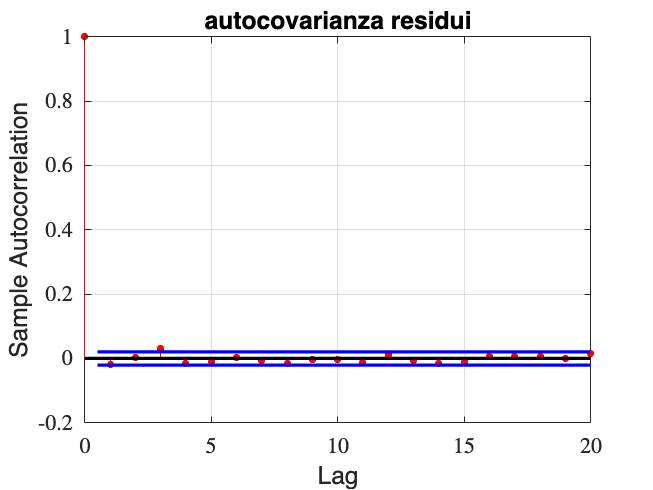


res = infer(mdl, ys);

% analisi residui
figure
autocorr(res)
title("autocovarianza residui")

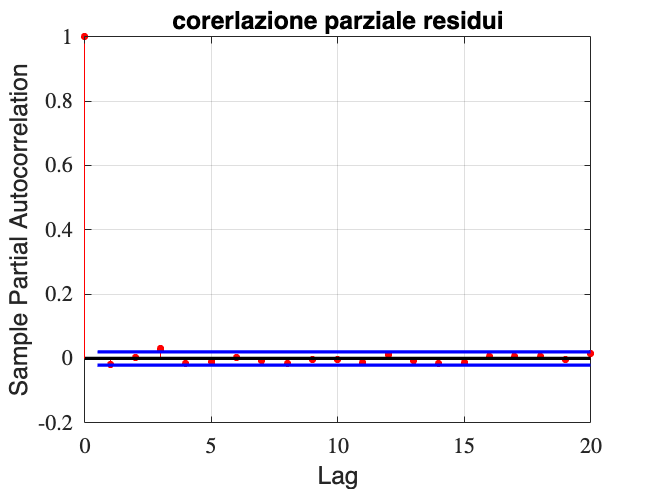


figure
parcorr(res)
title("corerlazione parziale residui")

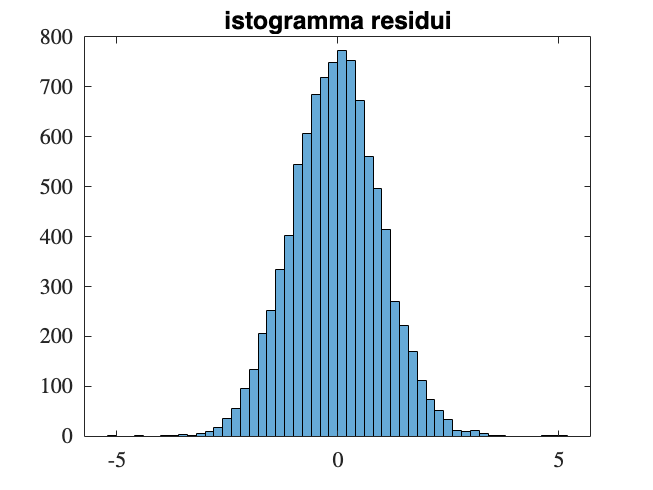


figure
grid on
axis tight
histogram(res)
title("istogramma residui")

## Che forma ha la densità spettrale di potenza?

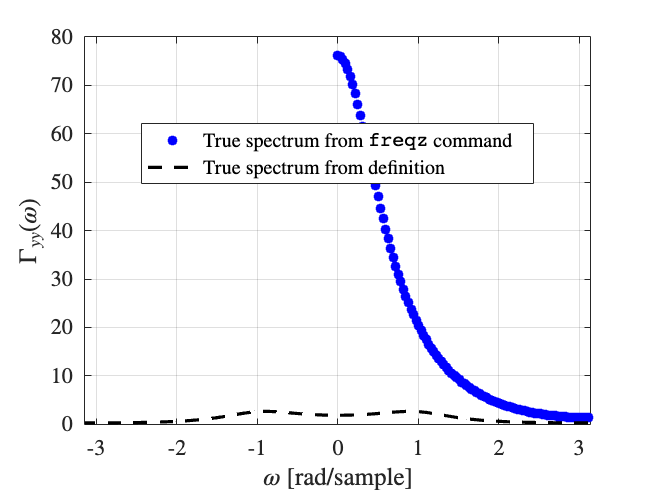

C = cell2mat(mdl.MA);
A = cell2mat(mdl.AR);

Hz = tf(C,A,1);

num_frequencies = 100;  % points onto which to evaluate the frequency response
[Hz_frf, w_norm_eval] = freqz(C, A, num_frequencies); % frequency response of H(z)
Hz_frf_mag = abs(Hz_frf).^2; % squared modulus of the frequency response

% gamma_yy_hat = lambda_2 .* Hz_frf_mag;
%
% w_norm = -3*pi:pi/num_frequencies:3*pi; % normalized pulsations where compute the spectrum

% temp = zeros(size(gamma_yy_hat));
% for i = 1:size(gamma_yy_hat,1)
%     if(size(gamma_yy_hat,1) ~= i)
%         temp(i,1) = gamma_yy_hat(size(gamma_yy_hat,1)-i,1);
%     end
% end
%
% gamma_yy_hat = [temp;gamma_yy_hat];
%
% figure
% plot([1:size(gamma_yy_hat,1)],gamma_yy_hat);
% title('y')

% Compute power spectral density using the definition
Gamma_ee = 1; % psd of the white noise (its variance)
w_norm = -3*pi:pi/num_frequencies:3*pi; % normalized pulsations where compute the spectrum
Gamma_yy = 1./abs(1 - A(1)*exp(1j*w_norm) - A(2)*exp(2*1j*w_norm)).^2 * Gamma_ee;


figure
plot(w_norm_eval, Hz_frf_mag, 'b*', 'linewidth', 2)
hold on;
plot(w_norm, Gamma_yy, 'k--' ,'linewidth', 2); grid on; xlim([-pi, pi]);
xlabel('$\omega$ [rad/sample]', 'interpreter', 'latex'); ylabel('$\Gamma_{yy}(\omega)$', 'interpreter', 'latex');
legend('True spectrum from $\texttt{freqz}$ command', 'True spectrum from definition', 'Location', 'best')

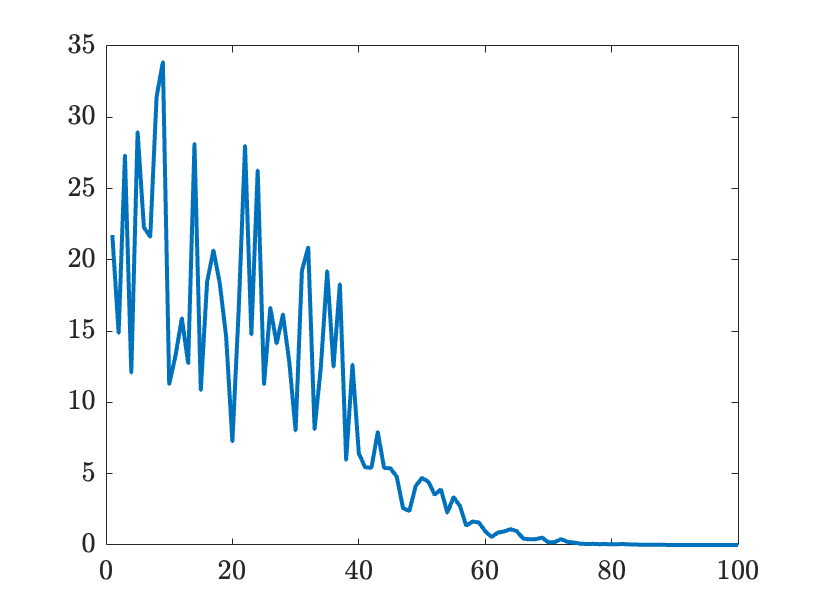



% Estimation with pwelch
WINDOW = []; % 100 - 200
gamma_yy_hat_pwelch = pwelch(ys, WINDOW, [], w_norm_eval);
gamma_yy_hat_pwelch = 2*pi * gamma_yy_hat_pwelch;
% the pwelch method returns a scaled psd, see documentation
% at https://it.mathworks.com/help/signal/ref/pwelch.html

figure
plot([1:size(gamma_yy_hat_pwelch,1)],gamma_yy_hat_pwelch)